clear
T_1 = -20; %C
% T_2 = ? %
T_4 = -10; %C

% p_1 = 1.338 % bar % tryk


% rho = 6.76 % kg


%%%%%%%%%%%%%%          R134a        %%%%%%%%%%%%%%%%%%%%%
%                         R1

L = 7%sym('L', 'positive') %, 'positive'

L =      7


% syms L
% L = 1.5 % m
nu = 0.000001511; %m^2 / s

eta_1 = 0.00001022; %kg/(m*s)

q_m = 0.00338; %kg/s

d_1 = (9.52 - 2 * 0.8) / 1000 % m %indre diameter af kobber rør

d_1 =                    0.00792



g = 9.82; % m/s^2

lambda_1 = 0.01036 %[W/m-K]

lambda_1 =                    0.01036



r_fordamp = 211.2 * 1000% J/kg%m * l_fd

r_fordamp =       211200





Re_1 = q_m * d_1 / (pi/4 * d_1^2 * eta_1)

Re_1 =           53168.0511228336



K_f = r_fordamp / (L * g) 

K_f =           3072.44690136747


 
NUs_1 = 0.0075 * (Re_1^2 * K_f )^0.40

NUs_1 =           1123.50655608429



alpha_1 = NUs_1 * lambda_1 / d_1;
alpha_1_ = vpa(alpha_1,5)

$$alpha\_1\_ = 1469.6$$


A_1 = pi*d_1*L

A_1 =          0.174169896715018



R_1 = vpa(1 / (alpha_1 * A_1), 3) % K/W

$$R\_1 = 0.00391$$




%%%%%%%%%%%%%%%%%%%%%  Kobber rør   %%%%%%%%%%%%%
%                         R2

r_1 = d_1/2 % m % indre radius

r_1 =                    0.00396


d_2 = 9.52 / 1000 % m ydre diamter af rør

d_2 =                    0.00952


r_2 = d_2 /2  % m % ydre radius

r_2 =                    0.00476



lambda_2 = 372; % W/(m*K) Tabel 10.11 i thermo bog version 4


R_2 = (r_2 / r_1) / (lambda_2 * 2 * pi * L)

R_2 =       7.34667653025475e-05




%%%%%%%%%%%%%%%%%%%%    Brine  20% saltblanding NaCl  %%%%%%%%%%%%%%%%%
%                       R3

T_3 =  -18; % C gæt

nu_3 = 0.000003921; %[m^2/s]
c_p_3 = 3.354 * 1000; %[J/Kg * K]
rho_3 = 1162; % kg/m^3
lambda_3 = 0.5172; % W/(m*K)

a_3 = lambda_3 / (c_p_3 * rho_3)

a_3 =       1.32705624440004e-07


beta_3 =  0.000021; %1/K  % chat bot



% Ra = (g * beta_3 * (T_4 - T_3) * d_2^3) / (nu^2 * a_3)

% n_3 = 1/4; % 1/3 for turbolent % 1/4 for laminart
% C_3 = 0.10 % % turbulent strømning
% NUs_3 = C_3 * Ra^n_3

eta_3 = nu_3 * rho_3

eta_3 =                0.004556202



%19l/min

s =  19 / (60 * 10 * 10 * 10); %pumpen  kan lever 19L/min
% min1/s60
% 1m^3/L1000
d_pumpe = 0.01; % m

d_brine1 = 0.18;
A_brine1 = pi * (d_brine1/2)^2;
d_brine2 = 0.20;
A_brine2 = pi * (d_brine2/2)^2;

% A_pumpe = A_brine2 - A_brine1
% A_pumpe = 0.06
A_pumpe = pi * (d_pumpe/2)^2

A_pumpe =       7.85398163397448e-05



c = 0.5%s / A_pumpe %pga sug gange med 2

c =                        0.5



% c = 1

Re_3 = c / (pi/4 * d_2^2 * eta_3)

Re_3 =           1541712.01091049


vpa(Re_3,6)

$$ans = 1541710.0$$



Pr_3 = eta_3 * c_p_3 / lambda_3

Pr_3 =           29.5465999767981


Pr_v3 = Pr_3

Pr_v3 =           29.5465999767981


% NUs_3 = (0.60 + (0.387 * Ra^(1/6)) / (1 + (0.559/Pr_3)^(9/16))^(8/27) )^2
C_3 = 0.26;
m = 0.6;
n = 0.36;



NUs_3 = C_3 * Re_3^m * Pr_3^n * (Pr_3/Pr_v3)^(1/4)

NUs_3 =           4541.06800708318



alpha_3 = NUs_3 * lambda_3 / d_2 

alpha_3 =           246705.921561284



A_3 = pi * d_2 * L

A_3 =          0.209355734435224



R_3 = 1 / (alpha_3 * A_3)

R_3 =       1.93613468460539e-05


TOTAL udregninger

Phi_slush = 207%w 

Phi_slush =    207



R_tot_indre = R_1 + R_2 + R_3

$$R\_tot\_indre = 0.0039995880075063892985923804518356$$


R_ydre = 0.083%51397%361 % K/W 

R_ydre =                      0.083


R_tot = R_ydre + R_tot_indre

$$R\_tot = 0.086999588007506389298592380451836$$

T_4 = -2

T_4 =     -2



R_tot_eq1 = R_1 + R_2  +  R_3 + R_ydre; %+ R_3
R_tot_eq2 = (T_4 - T_1) / Phi_slush;

Phi_slush = (T_4 - T_1) / R_tot

$$Phi\_slush = 206.89753149689567016876588390316$$


% L_fordamp = solve(R_tot_eq1 == R_tot_eq2, L)


% for i = 1:20
%     T = -5:0.5:4.5;
%     R_tot_eq1 = R_1 + R_2 + R_3 + R_ydre;
%     R_tot_eq2 = (T_1 - T(i)) / Phi_slush;
%     L_fordamp(i) = double(solve(R_tot_eq1 == R_tot_eq2, L)); 
% end


% L_fun = R_tot_eq1 - R_tot_eq2

% plot(T,L_fordamp)



L = linspace(0.1,4,100)%0.1:0.1:2;

L =                        0.1         0.139393939393939         0.178787878787879         0.218181818181818         0.257575757575758         0.296969696969697         0.336363636363636         0.375757575757576         0.415151515151515         0.454545454545455         0.493939393939394         0.533333333333333         0.572727272727273         0.612121212121212         0.651515151515151         0.690909090909091          0.73030303030303          0.76969696969697         0.809090909090909         0.848484848484848         0.887878787878788         0.927272727272727         0.966666666666667          1.00606060606061          1.04545454545455          1.08484848484848          1.12424242424242          1.16363636363636           1.2030303030303          1.24242424242424          1.28181818181818          1.32121212121212          1.36060606060606                       1.4          1.43939393939394          1.47878787878788          1.51818181818182          1.55757575757576        

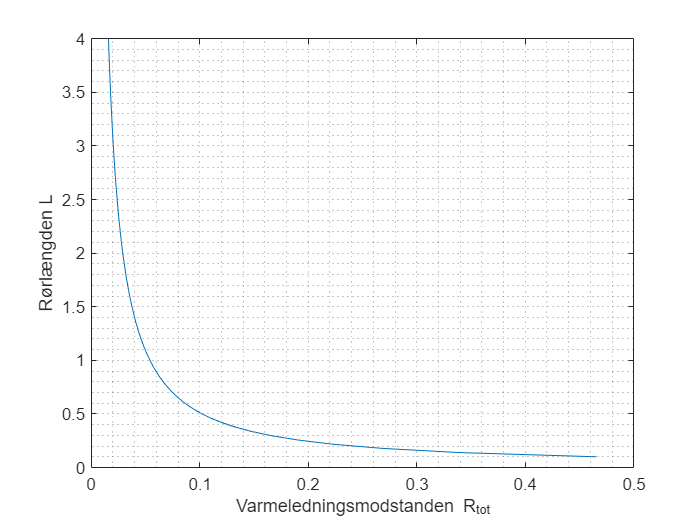


for i = 1:100

nu = 0.000001511; %m^2 / s

eta_1 = 0.00001022; %kg/(m*s)

q_m = 0.00338; %kg/s

d_1 = (9.52 - 2 * 0.8) / 1000 ;% m %indre diameter af kobber rør

g = 9.82; % m/s^2

lambda_1 = 0.01036; %[W/m-K]

r_fordamp = 211.2 * 1000;% J/kg%m * l_fd



Re_1 = q_m * d_1 / (pi/4 * d_1^2 * eta_1);

K_f = r_fordamp / (L(i) * g) ;
 
NUs_1 = 0.0075 * (Re_1^2 * K_f )^0.40;

alpha_1 = NUs_1 * lambda_1 / d_1;
alpha_1_ = vpa(alpha_1,3);

A_1 = pi*d_1*L(i);

R_1 = vpa(1 / (alpha_1 * A_1), 3); % K/W



%%%%%%%%%%%%%%%%%%%%%  Kobber rør   %%%%%%%%%%%%%
%                         R2

r_1 = d_1/2; % m % indre radius
d_2 = 9.52 / 1000; % m ydre diamter af rør
r_2 = d_2 /2 ; % m % ydre radius

lambda_2 = 372; % W/(m*K) Tabel 10.11 i thermo bog version 4


R_2 = (r_2 / r_1) / (lambda_2 * 2 * pi * L(i));


%%%%%%%%%%%%%%%%%%%%    Brine  20% saltblanding NaCl  %%%%%%%%%%%%%%%%%
%                       R3

T_3 =  -18; % C gæt

nu_3 = 0.000003921; %[m^2/s]
c_p_3 = 3.354 * 1000; %[J/Kg * K]
rho_3 = 1162; % kg/m^3
lambda_3 = 0.5172; % W/(m*K)

a_3 = lambda_3 / (c_p_3 * rho_3);
beta_3 =  0.000021; %1/K  % chat bot

Ra = (g * beta_3 * (T_4 - T_3) * d_2^3) / (nu^2 * a_3);

% n_3 = 1/4; % 1/3 for turbolent % 1/4 for laminart
% C_3 = 0.10 % % turbulent strømning
% NUs_3 = C_3 * Ra^n_3

eta_3 = nu_3/rho_3;

Pr_3 = eta_3 * c_p_3 / lambda_3;

NUs_3 = (0.60 + (0.387 * Ra^(1/6)) / (1 + (0.559/Pr_3)^(9/16))^(8/27) )^2;

alpha_3 = NUs_3 * lambda_3 / d_2 ;

A_3 = pi * d_2 * L(i);

R_3 = 1 / (alpha_3 * A_3);


R_tot(i) = (R_1 + R_2 + R_3);

end

plot(R_tot, L)
xlabel('Varmeledningsmodstanden R_{tot}')
ylabel('Rørlængden L')
grid('minor')


alpha_3

alpha_3 =           814.742747596319


alpha_1

alpha_1 =           1838.33816848555


alpha_1_

$$alpha\_1\_ = 1840.0$$